% clear
% load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20221103_1\IBM_bounded_sx=2_sy=512_nbins=12_nmax=2_del=0.001_b=10_p=1.mat')
% saveto_filepath = 'C:/Users/eschlatter/Dropbox/DispersalEvolution/output_simulations/20221103_1';
% 
% % save smaller files with important variables
% save(strcat(saveto_filepath,'/pop_1_nmax=',num2str(nmax),'.mat'),"pop")
% save(strcat(saveto_filepath,'/dtime_1_nmax=',num2str(nmax),'.mat'),"dtime_avg","dtime_std")



% % put runs together
% clear
% 
% load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20221103_1\dtime_nmax=0.mat')
% dtime_avg_1_nmax_0 = dtime_avg;
% dtime_std_1_nmax_0 = dtime_std;
% load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20221103_2\dtime_nmax=0.mat')
% dtime_avg_2_nmax_0 = dtime_avg;
% dtime_std_2_nmax_0 = dtime_std;
% load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20221103_3\dtime_nmax=0.mat')
% dtime_avg_3_nmax_0 = dtime_avg;
% dtime_std_3_nmax_0 = dtime_std;
% load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20221103_4\dtime_nmax=0.mat')
% dtime_avg_4_nmax_0 = dtime_avg;
% dtime_std_4_nmax_0 = dtime_std;
% 
% clear dtime_avg dtime_std
% 
% save('C:/Users/eschlatter/Dropbox/DispersalEvolution/output_simulations/all_20221103/dtime_nmax=0')
% 
% 
% clear
% 
% load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20221103_1\pop_nmax=0.mat')
% pop_1_nmax_0 = pop;
% load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20221103_2\pop_nmax=0.mat')
% pop_2_nmax_0 = pop;
% load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20221103_3\pop_nmax=0.mat')
% pop_3_nmax_0 = pop;
% load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20221103_4\pop_nmax=0.mat')
% pop_4_nmax_0 = pop;
% 
% clear pop
% 
% save('C:/Users/eschlatter/Dropbox/DispersalEvolution/output_simulations/all_20221103/pop_nmax=0')


### nmax = 0

t =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [3 3]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


clear
figure
clf
t = tiledlayout(3,3)


begmin = 1;
begmax = 2;
intmin = 20000;
intmax = 40000;
endmin = 200000;
endmax = 500000;

%% dynamics plot, with time ranges marked
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20221103_1\dtime_nmax=0.mat')

Error using load
Unable to find file or directory 'C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20221103_1\dtime_nmax=0.mat'.


nexttile([1,3])
hold on
errorbar(dtime_avg,dtime_std)
rectangle('Position',[begmin 0 (begmax-begmin) 1],'LineWidth',2)
rectangle('Position',[intmin 0 (intmax-intmin) 1],'LineWidth',1)
rectangle('Position',[endmin 0 (endmax-endmin) 1],'LineWidth',1)
axis([0 500000 0 1.1])
title('Displacement Strategy Evolution')
xlabel('Generation')
ylabel('Probability')
hold off

%% beginning plot
clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\files_runsims\pop_uniform_sx=2_sy=512_nbins=12.mat')
nexttile([2,1])
title('Beginning')
kernelcosts(mean(pop(:,1:12),1),0,1)

%% intermediate plot
clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20221103_1\dtime_nmax=0.mat')
v_intermed = dtime_avg(1:40000,:);
nexttile([2,1])
title('Middle')
dtimecosts_error_plot(v_intermed,0,20000,1)

%% ESS plot
clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20221103_1\dtime_nmax=0.mat')

% plot distribution of means over last 3x10^5 generations, for the 4
% different runs, to compare across runs
% 
% hold on
% distributionPlot(dtime_avg_1_nmax_0(200000:500000,:),'color','r','showMM',0)
% distributionPlot(dtime_avg_2_nmax_0(200000:500000,:),'color','b','showMM',0)
% distributionPlot(dtime_avg_3_nmax_0(200000:500000,:),'color','g','showMM',0)
% distributionPlot(dtime_avg_4_nmax_0(200000:500000,:),'color','y','showMM',0)
% hold off
% % conclusion: they're pretty similar. Let's just use the first one.

% sample a bunch of kernels from the last 3x10^5 generations
% for each kernel sampled, calculate the components of selection
nexttile([2,1])
title('End')
[a, b, c, d] = dtimecosts_error_plot(dtime_avg,0,200000,1)
legend('kernel','','mortality','kin competition','total benefit')
% using the other three runs, the result is basically the same
% dtimecosts_error_plot(dtime_avg_2_nmax_0,0,200000,1) 
% dtimecosts_error_plot(dtime_avg_3_nmax_0,0,200000,1)
% dtimecosts_error_plot(dtime_avg_4_nmax_0,0,200000,1)


### nmax = 1

clear
figure
clf
t = tiledlayout(3,3)

begmin = 1;
begmax = 2;
intmin = 20000;
intmax = 40000;
endmin = 200000;
endmax = 500000;

%% dynamics plot, with time ranges marked
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20221103_1\dtime_1_nmax=1.mat')

nexttile([1,3])
hold on
errorbar(dtime_avg,dtime_std)
rectangle('Position',[begmin 0 (begmax-begmin) 1],'LineWidth',2)
rectangle('Position',[intmin 0 (intmax-intmin) 1],'LineWidth',1)
rectangle('Position',[endmin 0 (endmax-endmin) 1],'LineWidth',1)
axis([0 500000 0 1.1])
title('Displacement Strategy Evolution')
xlabel('Generation')
ylabel('Probability')
hold off

%% beginning plot
clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\files_runsims\pop_uniform_sx=2_sy=512_nbins=12.mat')
nexttile([2,1])
title('Beginning')
kernelcosts(mean(pop(:,1:12),1),1,1)

%% intermediate plot
clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20221103_1\dtime_1_nmax=1.mat')
v_intermed = dtime_avg(1:40000,:);
nexttile([2,1])
title('Middle')
dtimecosts_error_plot(v_intermed,1,20000,1);

%% ESS plot
clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20221103_1\dtime_1_nmax=1.mat')

% plot distribution of means over last 3x10^5 generations, for the 4
% different runs, to compare across runs
% 
% hold on
% distributionPlot(dtime_avg_1_nmax_0(200000:500000,:),'color','r','showMM',0)
% distributionPlot(dtime_avg_2_nmax_0(200000:500000,:),'color','b','showMM',0)
% distributionPlot(dtime_avg_3_nmax_0(200000:500000,:),'color','g','showMM',0)
% distributionPlot(dtime_avg_4_nmax_0(200000:500000,:),'color','y','showMM',0)
% hold off
% % conclusion: they're pretty similar. Let's just use the first one.

% sample a bunch of kernels from the last 3x10^5 generations
% for each kernel sampled, calculate the components of selection
nexttile([2,1])
title('End')
[a, b, c, d] = dtimecosts_error_plot(dtime_avg,1,200000,1);
legend('kernel','','mortality','kin competition','total benefit')
% using the other three runs, the result is basically the same
% dtimecosts_error_plot(dtime_avg_2_nmax_0,0,200000,1) 
% dtimecosts_error_plot(dtime_avg_3_nmax_0,0,200000,1)
% dtimecosts_error_plot(dtime_avg_4_nmax_0,0,200000,1)



### nmax = 2

clear
figure
clf
t = tiledlayout(3,3)

begmin = 1;
begmax = 2;
intmin = 20000;
intmax = 40000;
endmin = 200000;
endmax = 500000;

%% dynamics plot, with time ranges marked
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20221103_1\dtime_1_nmax=2.mat')

nexttile([1,3])
hold on
errorbar(dtime_avg,dtime_std)
rectangle('Position',[begmin 0 (begmax-begmin) 1],'LineWidth',2)
rectangle('Position',[intmin 0 (intmax-intmin) 1],'LineWidth',1)
rectangle('Position',[endmin 0 (endmax-endmin) 1],'LineWidth',1)
axis([0 500000 0 1.1])
title('Displacement Strategy Evolution, nmax=2')
xlabel('Generation')
ylabel('Probability')
hold off

%% beginning plot
clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\files_runsims\pop_uniform_sx=2_sy=512_nbins=12.mat')
nexttile([2,1])
title('Beginning')
kernelcosts(mean(pop(:,1:12),1),2,1)

%% intermediate plot
clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20221103_1\dtime_1_nmax=2.mat')
v_intermed = dtime_avg(1:40000,:);
nexttile([2,1])
title('Middle')
dtimecosts_error_plot(v_intermed,2,20000,1);

%% ESS plot
clear
load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20221103_1\dtime_1_nmax=2.mat')

% plot distribution of means over last 3x10^5 generations, for the 4
% different runs, to compare across runs
% 
% hold on
% distributionPlot(dtime_avg_1_nmax_0(200000:500000,:),'color','r','showMM',0)
% distributionPlot(dtime_avg_2_nmax_0(200000:500000,:),'color','b','showMM',0)
% distributionPlot(dtime_avg_3_nmax_0(200000:500000,:),'color','g','showMM',0)
% distributionPlot(dtime_avg_4_nmax_0(200000:500000,:),'color','y','showMM',0)
% hold off
% % conclusion: they're pretty similar. Let's just use the first one.

% sample a bunch of kernels from the last 3x10^5 generations
% for each kernel sampled, calculate the components of selection
nexttile([2,1])
title('End')
[a, b, c, d] = dtimecosts_error_plot(dtime_avg,2,200000,1);
legend('kernel','','mortality','kin competition','total benefit')
% using the other three runs, the result is basically the same
% dtimecosts_error_plot(dtime_avg_2_nmax_0,0,200000,1) 
% dtimecosts_error_plot(dtime_avg_3_nmax_0,0,200000,1)
% dtimecosts_error_plot(dtime_avg_4_nmax_0,0,200000,1)


for rep = 1:4
    for nmax=0:2
        load(strcat('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20221103_',num2str(rep),'\dtime_',num2str(rep),'_nmax=',num2str(nmax),'.mat'))
        comboplot2(dtime_avg,dtime_std,nmax,rep,20000,40000,200000,500000)
    end
end


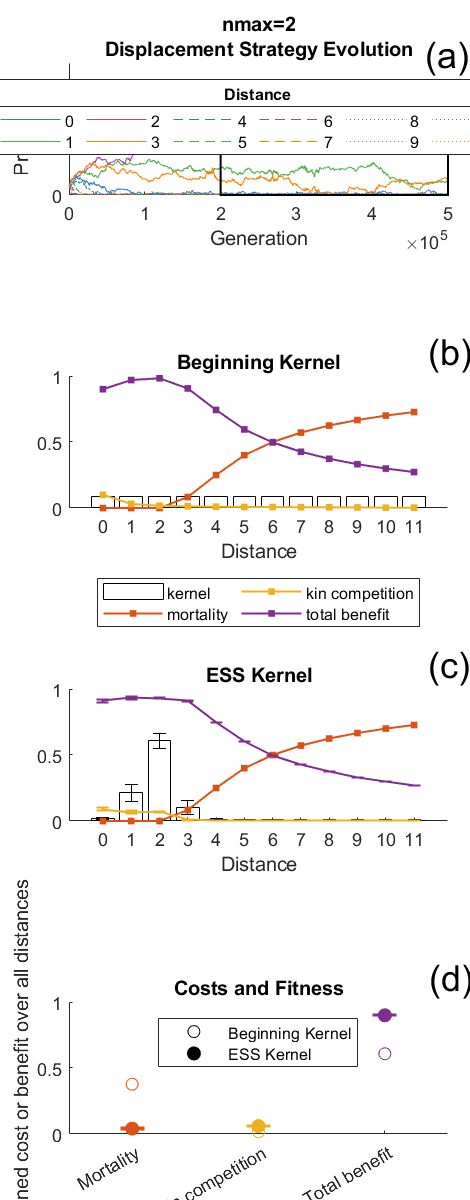

load('C:\Users\eschlatter\Dropbox\DispersalEvolution\output_simulations\20221103_1\dtime_1_nmax=2.mat')
comboplot4(dtime_avg,dtime_std,2,1,200000,500000)